Consider a slide pendulum as follows

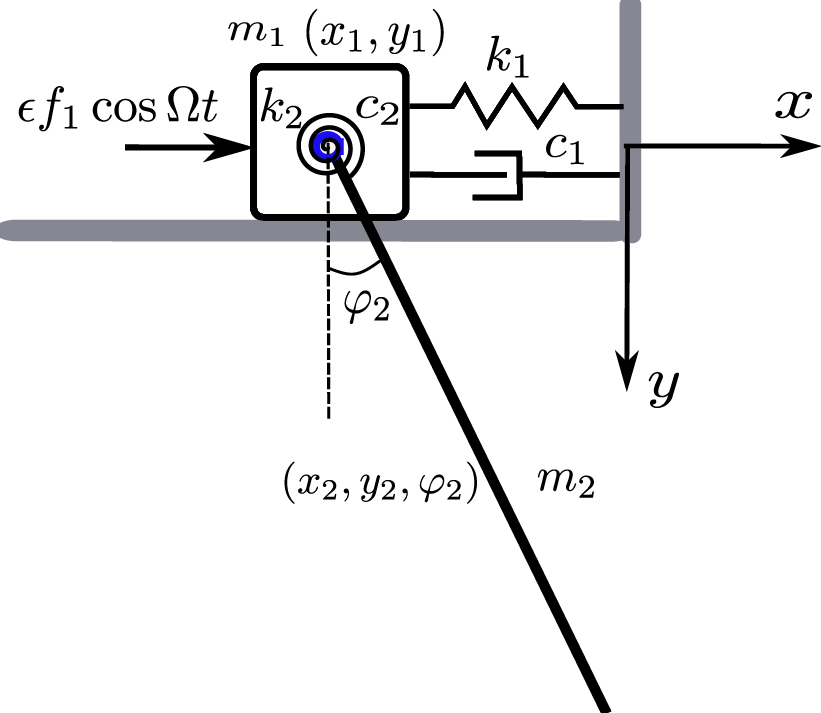

When there is no configuration constraints, the equation of motion is given by (the $\phi_2$ is defined differently here and the direction of $y$ axis is flipped)


$$m_1\ddot{x}_1+c_1\dot{x}_1+k_1x_1=p\cos\omega t,\\
m_1\ddot{y}_1=m_1g,\\
m_2\ddot{x}_2=0,\\
m_2\ddot{y}_2=m_2g,\\
J_2\ddot{\phi}_2+c_2\dot{\phi}_2+k_2\phi_2=0.$$


With configuration constraints considered, we add


$$g_1=y_1=0,\\
g_2=x_2-(x_1+0.5l\sin\phi_2),\\
g_3=y_2-(y_1+0.5l\cos\phi_2).$$


and the equation of motion is modifed as


$$\mathbf{M}\ddot{\mathbf{q}}+\mathbf{g}_\mathbf{q}^\top\mathbf{\mu}=\mathbf{f}$$



$$m_1\ddot{x}_1+c_1\dot{x}_1+k_1x_1-\mu_2=p\cos\omega t,\\
m_1\ddot{y}_1+\mu_1-\mu_3=m_1g,\\
m_2\ddot{x}_2+\mu_2=0,\\
m_2\ddot{y}_2+\mu_3=m_2g,\\
J_2\ddot{\phi}_2+c_2\dot{\phi}_2+k_2\phi_2-0.5l\mu_2\cos\phi_2+0.5l\mu_3\sin\phi_2=0.$$


To fit the framework of SSMTool, we know the rest state is an equilibrium, and then take the following transformation


$$y_2=\hat{y}_2+0.5l, \mu_1=\hat{\mu}_1+m_1g+m_2g,\mu_3=\hat{\mu}_3+m_2g$$


and obtain


$$m_1\ddot{x}_1+c_1\dot{x}_1+k_1x_1-\lambda_2=p\cos\omega t,\\
m_1\ddot{y}_1+\hat{\mu}_1-\hat{\mu}_3=0,\\
m_2\ddot{x}_2+\mu_2=0,\\
m_2\ddot{\hat{y}}_2+\hat{\mu}_3=0,\\
J_2\ddot{\phi}_2+c_2\dot{\phi}_2+k_2\phi_2-0.5l\mu_2\cos\phi_2+0.5l(\hat{\mu}_3+m_2g)\sin\phi_2=0.$$



$$g_1=y_1=0,\\
g_2=x_2-(x_1+0.5l\sin\phi_2),\\
g_3=\hat{y}_2-y_1+0.5l(1-\cos\phi_2).$$


We further introduce auxiliary variable $u_1=\sin\phi_2$ and $u_2=1-\cos\phi_2$, yielding


$$m_1\ddot{x}_1+c_1\dot{x}_1+k_1x_1-\mu_2=p\cos\omega t,\\
m_1\ddot{y}_1+\hat{\mu}_1-\hat{\mu}_3=0,\\
m_2\ddot{x}_2+\mu_2=0,\\
m_2\ddot{\hat{y}}_2+\hat{\mu}_3=0,\\
J_2\ddot{\phi}_2+c_2\dot{\phi}_2+k_2\phi_2-0.5l\mu_2(1-u_2)+0.5l(\hat{\mu}_3+m_2g)u_1=0,$$



$$g_1=y_1=0,\\
g_2=x_2-(x_1+0.5lu_1),\\
g_3=\hat{y}_2-y_1+0.5lu_2,\\
\dot{u}_1=(1-u_2)\dot{\phi}_2\\
u_1^2+(1-u_2)^2=1.$$


Let $z=(x_1,y_1,x_2,\hat{y}_2,\phi_2,\dot{x}_1,\dot{y}_1,\dot{x}_2,\dot{\hat{y}}_2,\dot{\phi}_2,\mu_1,\mu_2,\mu_3,u_1,u_2)$, we have $\mathbf{B}\dot{\mathbf{z}}=\mathbf{A}\mathbf{z}+\mathbf{F}(\mathbf{z})$.

clear all

## Setup model

c1 =0.02;
c2 = 0.02;
k1 = 7.48;
k2 = 1;
[A,B,Fnl,Fext] = build_model(c1,c2,k1,k2);
DS = DynamicalSystem();
set(DS,'B',B,'A',A,'fnl',Fnl);
set(DS.Options,'Emax',15,'Nmax',20,'notation','multiindex')

**Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis();

10 nan/inf eigenvalues are removed
1 zero eigenvalues are removed

 The first 4 nonzero eigenvalues are given as 
  -0.0047 + 1.8522i
  -0.0047 - 1.8522i
  -0.0513 + 5.5561i
  -0.0513 - 5.5561i



Add forcing

epsilon = 0.08; % 0.1
kappas = [1; -1];
coeffs = [Fext Fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

## Autonomous SSM 

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex');
resonant_modes = [1 2 3 4]; % choose master spectral subspace
order = 13;                  % SSM expansion order
S.choose_E(resonant_modes)

sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
     0     2     1     0
     1     0     1     1
     2     1     0     0
     0     2     2     1
     1     0     2     2
     1     3     1     0
     2     1     1     1
     3     2     0     0
     4     0     0     1
     0     2     3     2
     0     5     2     0
     1     0     3     3
     1     3     2     1
     2     1     2     2
     2     4     1     0
     3     2     1     1
     4     0     1     2
     4     3     0     0
     5     1     0     1
     0     2     4     3
     0     5     3     1
     1     0     4     4
     1     3     3     2
     1     6     2     0
     2     1     3     3
     2     4     2     1
     3     2     2     2
     3     5     1     0
     4     0     2     3
     4     3     1     1
     5     1     1     2
     5     4     0     0
     6     2     0     1
     7     0     0     2
     0     1     1     1
     1     2     0     0
  

[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.43E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.59E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.39E-01 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 2.53E-01 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.94E-01 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 6.92E-01 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 1.04E+00 MB
Manifold computation time at order 9 = 00:00:01
Estimated memory usage at order  9 = 1.69E+00 MB
Manifold computation time at order 10 = 00:00:01
Estimated memory usage at order  10 = 2.43E+00 MB
Manifold computation time at order 11 = 00:00:02
Estimated memory usage at order  11 = 3.67E+00 MB
Manifold computation time 

#### Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

#### Compute invariance error measure with various $\varrho$ and orders

rhosamp = [0.2:0.2:1 1.5 2 2.5 3 3.5 4];
orders = [3 5]; % [3 5 7 9 11 13];
ntheta = 30;
nalpha = 10;
err = S.compute_auto_invariance_error(W0,R0,rhosamp,orders,ntheta,nalpha);

calculate error at order 3 and rho=2.000000e-01
calculate error at order 3 and rho=4.000000e-01
calculate error at order 3 and rho=6.000000e-01
calculate error at order 3 and rho=8.000000e-01
calculate error at order 3 and rho=1
calculate error at order 3 and rho=1.500000e+00
calculate error at order 3 and rho=2
calculate error at order 3 and rho=2.500000e+00
calculate error at order 3 and rho=3
calculate error at order 3 and rho=3.500000e+00
calculate error at order 3 and rho=4
calculate error at order 5 and rho=2.000000e-01
calculate error at order 5 and rho=4.000000e-01
calculate error at order 5 and rho=6.000000e-01
calculate error at order 5 and rho=8.000000e-01
calculate error at order 5 and rho=1
calculate error at order 5 and rho=1.500000e+00
calculate error at order 5 and rho=2
calculate error at order 5 and rho=2.500000e+00
calculate error at order 5 and rho=3
calculate error at order 5 and rho=3.500000e+00
calculate error at order 5 and rho=4


err = err/size(A,1); % normalized by phase dimension

Plot error measure

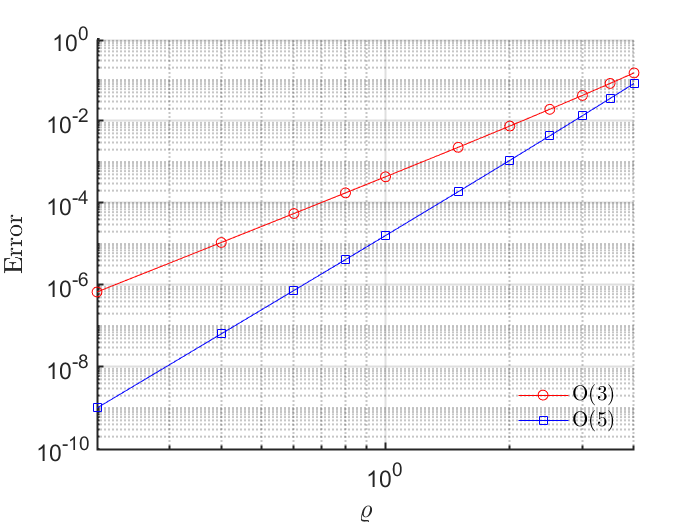

[RHO,ORDER]=meshgrid(rhosamp,orders);
% figure;
% surf(RHO,ORDER,err);
% set(gca, 'ZScale', 'log');
% xlabel('\varrho'); ylabel('order'); zlabel('Error');
lines = {'ro-','bs-','kv-','gd-','m<-','c>-'};
figure; hold on
for k=1:numel(orders)
    plot(rhosamp,err(k,:),lines{k},'DisplayName',['O(',num2str(orders(k)),')']);
end
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');
hl = legend('show','Location', 'Best'); 
set(hl, 'Interpreter','latex')
legend boxoff
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);
grid on
xlabel('$\varrho$','Interpreter',"latex",'FontSize',16);
ylabel('Error','Interpreter',"latex",'FontSize',16);

#### Transient response validation

We take an initial condition on SSM and perform forward simulation using both the reduced-order model and the full model

tf = 50;
nsteps = 1000;
q01 = [3.5*exp(1i*1) 3.5*exp(-1i*1) 0 0].'; % initial condition 1
q02 = [0 0 3.5*exp(1i*1) 3.5*exp(-1i*1)].'; % initial condition 2
q0  = [q01 q02];
z0s = []; trajs = cell(2,1);
for k=1:2
    z0 = reduced_to_full_traj(0,q0(:,k),W0);
    traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, [1:5 12 13], [], q0(:,k));
    z0s = [z0s z0];
    trajs{k} = traj;
end

Reference solution from forward simulation

options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = 0; omega = 2*pi; 
psp = [epf; omega];
func = @(t,x) slide_pend_ode(t,x,psp,c1,c2,k1,k2);
tInt = cell(2,1);
zInt = cell(2,1);
lamd2 = cell(2,1);
lamd3 = cell(2,1);
for k=1:2
    z0 = z0s(:,k);
    [tInt1, zInt1] = ode15s(func, [0 tf], z0([1 5 6 10]),options);
    [lamd2k,lamd3k] = cal_reaction_force(tInt1,zInt1,epf,omega,c1,c2,k1,k2);
    lamd2{k} = lamd2k;
    lamd3{k} = lamd3k;
    tInt{k} = tInt1;
    zInt{k} = zInt1;
end


----------------- initial condition 1 ------------


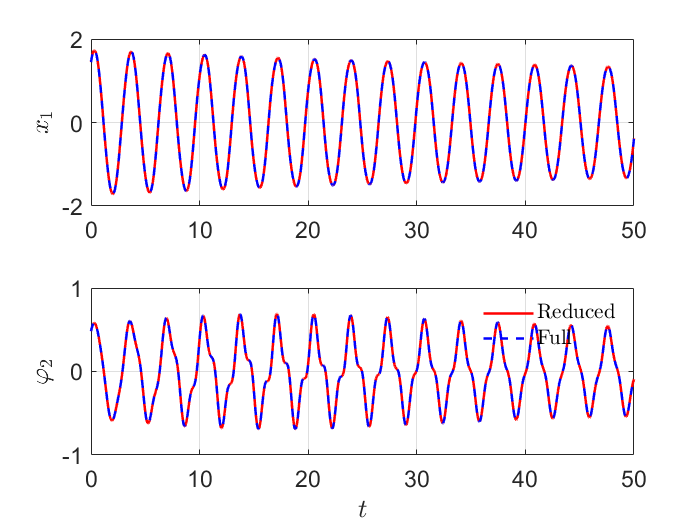

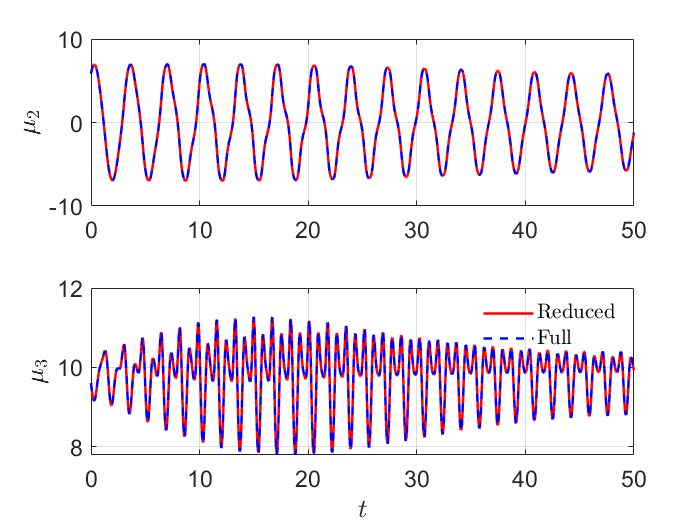

----------------- initial condition 2 ------------


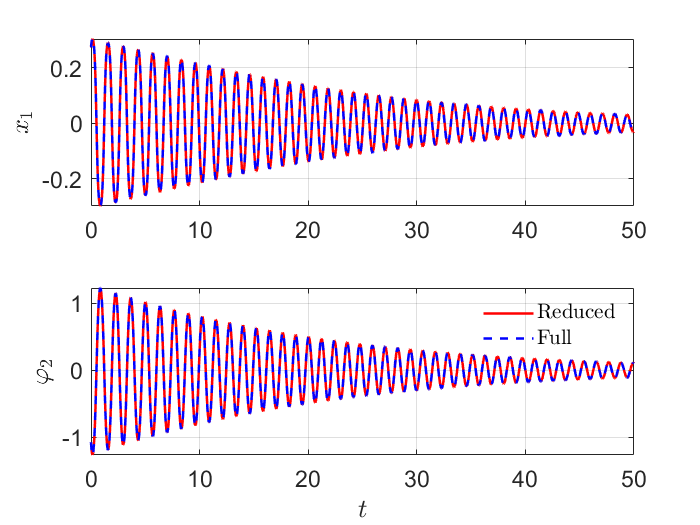

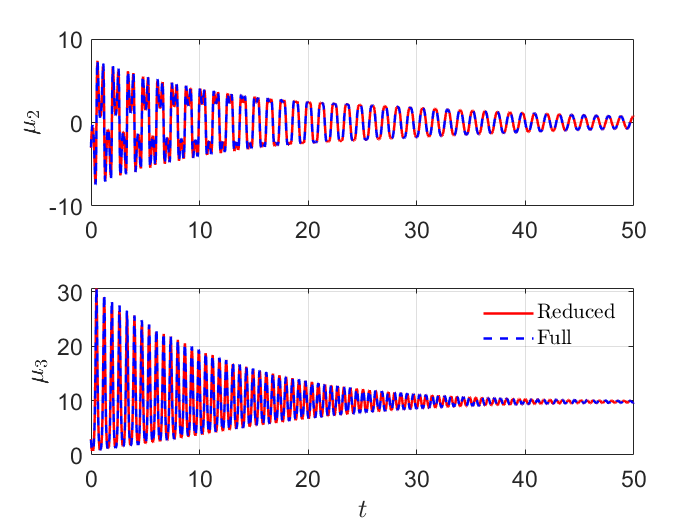

for k=1:2
    fprintf('----------------- initial condition %d ------------\n',k)
    traj = trajs{k};
    tIntk = tInt{k};
    zIntk = zInt{k};
    figure;
    subplot(2,1,1); hold on
    plot(traj.time,traj.phy(:,1),'r-','LineWidth',1.5); hold on
    plot(tIntk,zIntk(:,1),'b--','LineWidth',1.5);
    set(gca,'FontSize',14); grid on; box on
    ylabel('$x_1$','Interpreter',"latex",'FontSize',14);    
    subplot(2,1,2);
    plot(traj.time,traj.phy(:,5),'r-','LineWidth',1.5); hold on
    plot(tIntk,zIntk(:,2),'b--','LineWidth',1.5);
    set(gca,'FontSize',14); grid on;
    xlabel('$t$','Interpreter',"latex",'FontSize',14);
    ylabel('$\varphi_2$','Interpreter',"latex",'FontSize',14);
    legend('Reduced','Full','interpreter','latex');
    legend boxoff
    figure;
    subplot(2,1,1); hold on
    plot(traj.time,traj.phy(:,6),'r-','LineWidth',1.5);
    plot(tIntk,lamd2{k},'b--','LineWidth',1.5)
    set(gca,'FontSize',14); grid on; box on
    ylabel('$\mu_2$','Interpreter',"latex",'FontSize',14);        
    subplot(2,1,2); hold on
    plot(traj.time,traj.phy(:,7)+9.8,'r-','LineWidth',1.5);
    plot(tIntk,lamd3{k},'b--','LineWidth',1.5)
    set(gca,'FontSize',14); grid on; box on
    xlabel('$t$','Interpreter',"latex",'FontSize',14);
    ylabel('$\mu_3$','Interpreter',"latex",'FontSize',14);
    legend('Reduced','Full','interpreter','latex');
    legend boxoff    
end

We observed discrepancies in the fourth initial condition given $\varrho$ is too large.

## FRC computation

S = SSM(DS);
set(S.FRCOptions,'coordinates','polar')
set(S.Options, 'reltol', 0.5,'notation','multiindex');
resonant_modes = [1 2 3 4]; % choose master spectral subspace
mFreq = [1 3];              % internal resonance relation vector
outdof = [1 5];             % outdof

set(S.FRCOptions, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.contOptions, 'PtMX', 200, 'h_max', 0.5);               % continuation setting
set(S.FRCOptions,'method','continuation ep','outdof',outdof)
freqRange = [1.8 1.9];
% S.SSM_isol2ep('isol',resonant_modes,5,mFreq,'freq',freqRange,[1 5]);

The master subspace has internal resonances: [1  1  3  3]
*****************************************
Calculating FRC using SSM with master subspace: [1  2  3  4]
sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
     0     2     1     0
     1     0     1     1
     2     1     0     0
     0     2     2     1
     1     0     2     2
     1     3     1     0
     2     1     1     1
     3     2     0     0
     4     0     0     1
     0     2     3     2
     0     5     2     0
     1     0     3     3
     1     3     2     1
     2     1     2     2
     2     4     1     0
     3     2     1     1
     4     0     1     2
     4     3     0     0
     5     1     0     1
     0     2     4     3
     0     5     3     1
     1     0     4     4
     1     3     3     2
     1     6     2     0
     2     1     3     3
     2     4     2     1
     3     2     2     2
     3     5     1     0
     4     0     2     3
     4     3    

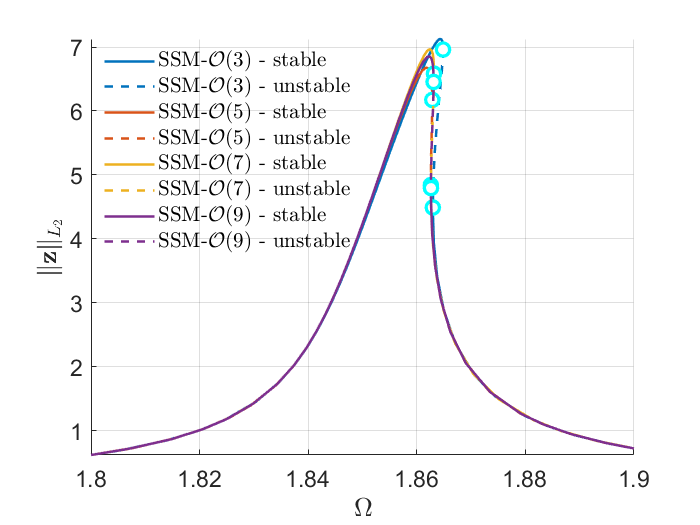

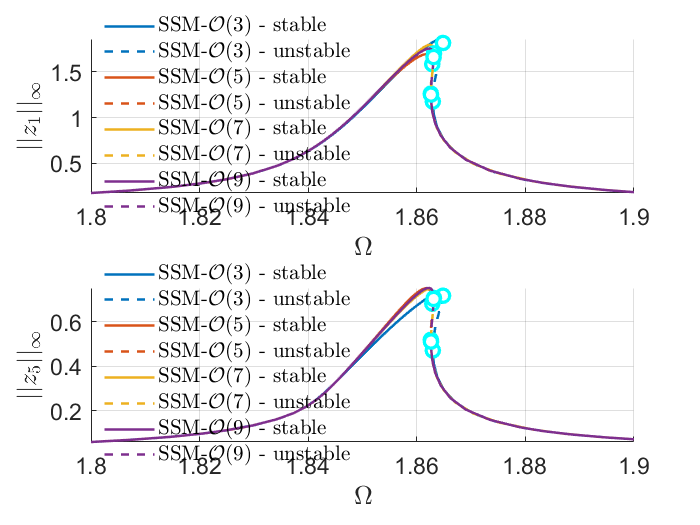

The master subspace has internal resonances: [1  1  3  3]
*****************************************
Calculating FRC using SSM with master subspace: [1  2  3  4]
sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
     0     2     1     0
     1     0     1     1
     2     1     0     0
     0     2     2     1
     1     0     2     2
     1     3     1     0
     2     1     1     1
     3     2     0     0
     4     0     0     1
     0     2     3     2
     0     5     2     0
     1     0     3     3
     1     3     2     1
     2     1     2     2
     2     4     1     0
     3     2     1     1
     4     0     1     2
     4     3     0     0
     5     1     0     1
     0     2     4     3
     0     5     3     1
     1     0     4     4
     1     3     3     2
     1     6     2     0
     2     1     3     3
     2     4     2     1
     3     2     2     2
     3     5     1     0
     4     0     2     3
     4     3    

set(S.FRCOptions,'outdof',outdof)
epsRange  = [0.01 3]*epsilon;
S.extract_FRC('freq',freqRange,[3 5 7 9]);

figssm = gcf;

We derive the ODE formulation of this system for the purpose of validation. 


$$T=0.5m_1\dot{x}_1^2+0.5m_2((\dot{x}_1+0.5l\cos\phi\dot{\phi})^2+(0.5l\sin\phi\dot{\phi})^2)+0.5J_2\dot{\phi}^2\\
=0.5m_1\dot{x}_1^2+0.5m_2(\dot{x}_1^2+l\dot{x}_1\cos\phi\dot{\phi}+0.25l^2\dot{\phi}^2)+0.5J_2\dot{\phi}^2$$


Based on Lagrangian equation

$\frac{d}{dt}\left(\frac{\partial T}{\partial\dot{q}}\right)-\frac{\partial T}{\partial q}=Q$, yielding

$\frac{\partial T}{\partial \dot{\phi}}=J_2\dot{\phi}+m_2\left(\dot{x}_1\frac{l}{2}\cos\phi+\frac{l^2}{4}\dot{\phi}\right)$, $\frac{\partial T}{\partial {\phi}}=m_2\left(-\dot{x}_1\frac{l}{2}\sin\phi\dot{\phi}\right)$


$$m_1\ddot{x}_1+m_2(\ddot{x}_1-0.5l\sin\phi\dot{\phi}^2+0.5l\cos\phi\ddot{\phi})=-c_1\dot{x}_1-k_1x_1+p\cos\omega t$$



$$J_2\ddot{\phi}+m_2\left(0.5l\ddot{x}_1\cos\phi+0.25l^2\ddot{\phi}\right)=-c_2\dot{\phi}-k_2\phi-0.5lm_2g\sin\phi$$


from which we obtain

$\left(\begin{array}{cc}m_1+m_2 & 0.5m_2l\cos\phi\\
0.5m_2l\cos\phi & J_2+0.25m_2l^2\end{array}\right)
\left(\begin{array}{c}\ddot{x}_1\\\ddot{\phi}\end{array}\right)=\left(\begin{array}{c}f_{x_1}\\ f_{\phi}\end{array}\right)$ and then


$$\left(\begin{array}{c}\ddot{x}_1\\\ddot{\phi}\end{array}\right)=\frac{1}{(m_1+m_2)(J_2+0.25m_2l^2)-0.25m_2l^2\cos\phi^2}
\left(\begin{array}{cc} J_2+0.25m_2l^2 & -0.5m_2l\cos\phi\\
-0.5m_2l\cos\phi & m_1+m_2\end{array}\right)
\left(\begin{array}{c}f_{x_1}\\ f_{\phi}\end{array}\right)$$


with 


$$f_{x_1}=-c_1\dot{x}_1-k_1x_1+p\cos\omega t+0.5m_2l\sin\phi\dot{\phi}^2$$



$$f_{\phi}=-c_2\dot{\phi}-k_2\phi-0.5lm_2g\sin\phi$$


options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = Fext(6)*epsilon; omega = 1.8; T = 2*pi/omega;
psp = [epf; omega];
func = @(t,x) slide_pend_ode(t,x,psp,c1,c2,k1,k2);
[~, x0] = ode15s(func, [0 200*T], zeros(4,1),options); % Transients
[ttor, xtor] = ode15s(func, [0 T], x0(end,:)',options);   % Approximate periodic orbit

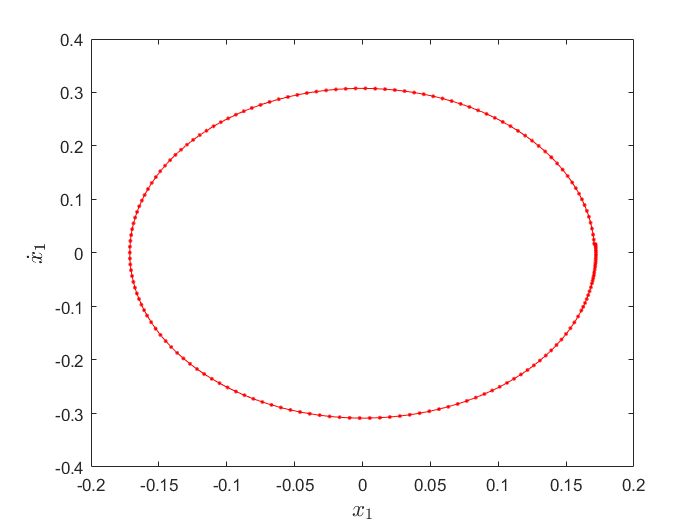

figure;
plot(xtor(:,1),xtor(:,3),'r.-');
xlabel('$x_1$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}_1$','Interpreter','latex','FontSize',14);

Continuation of periodic orbits with po-toolbox of COCO

prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 2, 'h_max', 100,'PtMX',200);
% prob = coco_set(prob, 'coll', 'NTST', 20);
odefunc = @(t,x,p) slide_pend_ode(t,x,p,c1,c2,k1,k2);
funcs = {odefunc};
coll_args = [funcs, {ttor, xtor, {'eps' 'Omega'}, psp}];
prob = ode_isol2po(prob, '', coll_args{:});
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(2))]);
ampdata.dof  = [1;2];
ampdata.zdim = 4;
prob = coco_add_func(prob, 'amp1', @amplitude, ampdata, 'regular', {'x1','x2'},...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);

cont_args = {1, {'Omega' 'po.period' 'x1' 'eps'}, freqRange};

fprintf('\n Run=''%s'': Continue primary family of periodic orbits.\n', ...
  'freq_resp');


 Run='freq_resp': Continue primary family of periodic orbits.



bd1  = coco(prob, 'freq_resp', [], cont_args{:});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.70e-03  5.83e+00    0.0    0.0    0.0
   1   1  1.00e+00  7.48e-02  2.62e-06  5.84e+00    0.0    0.0    0.0
   2   1  1.00e+00  1.66e-05  3.98e-13  5.84e+00    0.0    0.0    0.0
   3   1  1.00e+00  2.91e-12  7.63e-16  5.84e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         Omega    po.period           x1          eps
    0  00:00:00   5.8390e+00      1  EP      1.8000e+00   3.4907e+00   1.7470e-01   8.0000e-02
   10  00:00:01   1.0768e+01      2          1.8396e+00   3.4156e+00   6.2104e-01   8.0000e-02
   20  00:00:02   1.7928e+01      3          1.8457e+00   3.4042e+00   8.8221e-01   8.0000e-02
   30  00:00:04   2.5481e+01      4          1.8510e+00   3.3944e+00   1.1800e+00   8.0000e-02
   40  00:00:05   3.4760e+01      5          1.8562e+00   3.3850e+00   1.4955e+00   8.0000e-02
   50  0

Plot results

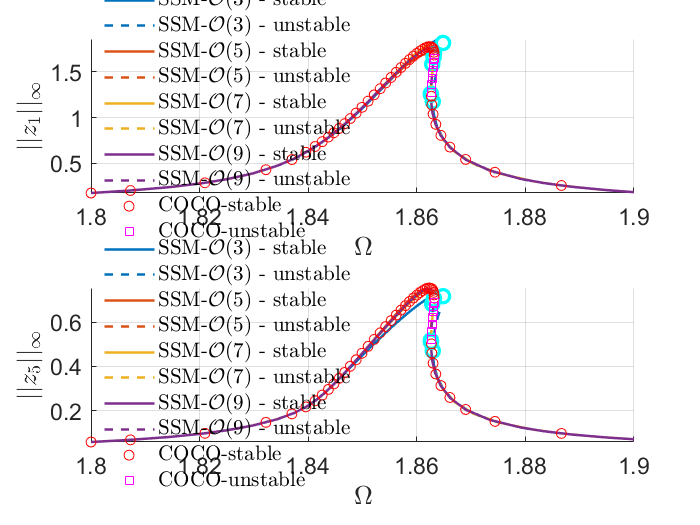

figure(figssm); hold on
subplot(2,1,1)
omcoco = coco_bd_col(bd1,'Omega'); x1coco = coco_bd_col(bd1,'x1');
eigcoco = coco_bd_col(bd1,'eigs'); stab = all(abs(eigcoco)<1,1);
omcoco = omcoco(1:2:end); x1coco = x1coco(1:2:end);
stab = stab(1:2:end); 
plot(omcoco(stab),x1coco(stab),'ro','DisplayName','COCO-stable');
plot(omcoco(~stab),x1coco(~stab),'ms','DisplayName','COCO-unstable');
subplot(2,1,2)
x2coco = coco_bd_col(bd1,'x2'); x2coco = x2coco(1:2:end);
plot(omcoco(stab),x2coco(stab),'ro','DisplayName','COCO-stable');
plot(omcoco(~stab),x2coco(~stab),'ms','DisplayName','COCO-unstable');